%--------------------------
clear all;
cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";
Datapath = "./data/";

MatNames1 = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
MatNames2 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
MatNames3 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
HDRNames_15 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];
HDRNames_30 = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
HDRNum_15 = [2,4,7,8,9,11,12,18,21,22,23,24,25,28,29];
HDRNum_30 = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];
ShapeNames = {'sphere','bunny','dragon','boardA','boardB','boardC'};

% load data
load(strcat(Datapath,'Exp1Mi_data.mat'));
load(strcat(Datapath,'Exp2Mi_data.mat'));
load(strcat(Datapath,'Exp1Th_data.mat'));
load(strcat(Datapath,'Exp2Th_data.mat'));
load(strcat(Datapath,'Exp3_data.mat'));
load(strcat(Datapath,'Inoue_data.mat'));
load(strcat(Datapath,'lummodel_data.mat'));
load(strcat(Datapath,'objmodel_data.mat'));

%変数
%{
Exp3HMSPT = Exp3RowHMSPT;
Exp3HMS = Exp3NormHMS;
Exp3HS = Exp3NormHS;
Exp3HM = Exp3NormHM;
Exp3H = Exp3NormH;
Exp3HM15 = Exp3Zs15bnyHM;
Exp3H15 = Exp3Zs15bnyH;
err_Exp3HMS = error_Exp3NormHMS;
err_Exp3HM = error_Exp3NormHM;
err_Exp3HS = error_Exp3NormHS;
err_Exp3H = error_Exp3NormH;
err_Exp3HM15 = error_Exp3HM15;
err_Exp3H15 = error_Exp3H15;
%}


Exp3HMSPT = Exp3RowHMSPT;
Exp3HMS = Exp3ZsHMS;
Exp3HS = Exp3ZsHS;
Exp3HM = Exp3ZsHM;
Exp3H = Exp3ZsH;
Exp3HM15 = Exp3Zs15bnyHM;
Exp3H15 = Exp3Zs15bnyH;
err_Exp3HMS = error_Exp3ZsHMS;
err_Exp3HM = error_Exp3ZsHM;
err_Exp3HS = error_Exp3ZsHS;
err_Exp3H = error_Exp3ZsH;
err_Exp3HM15 = error_Exp3HM15;
err_Exp3H15 = error_Exp3H15;


LumModelH = lummodelH;
Error_LumModelH = zeros(size(LumModelH));
LumModelNormH = lummodelNormH;
LumModelZsH = lummodelZsH;

ObjModelHMS = objmodelZsHMS;
ObjModelNormHMS = objmodelNormHMS;
ObjModelH = objmodelZsH;
ObjModelNormH = objmodelNormH;
ObjModelHS = objmodelZsHS;
ObjModelHM = objmodelZsHM;

%{
InoueHMSPT = InoueRowHMSPT;
InoueHMS = InoueNormHMS;
InoueHM = InoueNormHM;
InoueHS = InoueNormHS;
InoueH = InoueNormH;
InoueHM15 = InoueZs15bnyHM;
InoueH15 = InoueZs15bnyH;
err_InoueHMS = error_InoueNormHMS;
err_InoueHM = error_InoueNormHM;
err_InoueHS = error_InoueNormHS;
err_InoueH = error_InoueNormH;
err_InoueHM15 = error_InoueHM15;
err_InoueH15 = error_InoueH15;
%}

InoueHMSPT = InoueRowHMSPT;
InoueHMS = InoueZsHMS;
InoueHM = InoueZsHM;
InoueHS = InoueZsHS;
InoueH = InoueZsH;
InoueHM15 = InoueZs15bnyHM;
InoueH15 = InoueZs15bnyH;
err_InoueHMS = error_InoueZsHMS;
err_InoueHM = error_InoueZsHM;
err_InoueHS = error_InoueZsHS;
err_InoueH = error_InoueZsH;
err_InoueHM15 = error_InoueHM15;
err_InoueH15 = error_InoueH15;

Exp2MiHMPT15 = Exp2ThRowHMPT;
Exp2MiHM15 = Exp2MiZsHM;
Exp2MiH15 = Exp2MiZsH;
err_Exp2MiHM15 = error_Exp2MiZsHM;
err_Exp2MiH15 = error_Exp2MiZsH;

Exp2ThHMPT15 = Exp2ThRowHMPT;
Exp2ThHM15 = Exp2ThZsHM;
Exp2ThH15 = Exp2ThZsH;
err_Exp2ThHM15 = error_Exp2ThZsHM;
err_Exp2ThH15 = error_Exp2ThZsH;

Exp1MiHMP15 = Exp1MiRowHMP;
Exp1MiHM15 = Exp1MiZsHM;
Exp1MiH15 = Exp1MiZsH;
err_Exp1MiHM15 = error_Exp1MiZsHM;
err_Exp1MiH15 = error_Exp1MiZsH;

Exp1ThHMP15 = Exp1ThRowHMP;
Exp1ThHM15 = Exp1ThZsHM;
Exp1ThH15 = Exp1ThZsH;
err_Exp1ThHM15 = error_Exp1ThZsHM;
err_Exp1ThH15 = error_Exp1ThZsH;

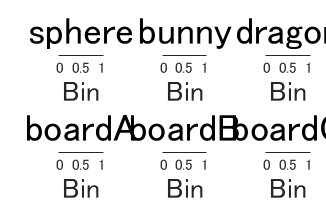

%---------------------------------------
% Exp3 光沢感応答 histgram
%---------------------------------------
Exp3RowHMSPT_per = permute(Exp3HMSPT,[2,3,1,4,5]);
Exp3RowHMSPT_reshape = reshape(Exp3RowHMSPT_per,size(Exp3RowHMSPT_per,1),size(Exp3RowHMSPT_per,2),[]);

%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        values = Exp3RowHMSPT_reshape(mat,shape,:);

        histogram(values,'BinEdges',0:0.025:1);
        xlabel('Bin','FontSize',14); 
        ylabel('Frequency','FontSize',14);
        title(sprintf('%s',string(ShapeNames(shape))),'FontSize',19);
        grid on;
    end
    plotname = sprintf('%s/Exp3_bin_%s_Hist.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

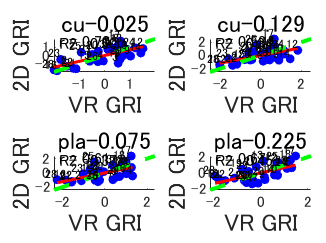

%-----------------------------------
% VR vs 2D HDR,Material coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_plot1(Exp3HM(:,mat),InoueHM(:,mat),coef_list,slop_list, ...
        'VR GRI','2D GRI',string(MatNames3(mat)),HDRNum_30,amp,predim)
end
plotname = strcat(ana_result, '/VRvs2D_Mat_Coef.jpg');
saveas(gcf, plotname);

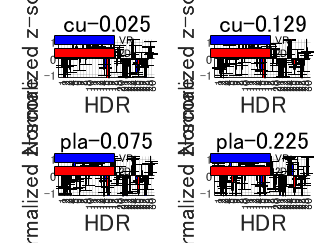


%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_histgram1(Exp3HM(:,mat),err_Exp3HM(:,mat),InoueHM(:,mat),err_InoueHM(:,mat), ...
        'HDR',HDRNum_30,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/VRvs2D_Mat_Hist.jpg');
saveas(gcf, plotname);

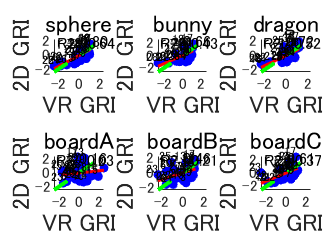

%-----------------------------------
% VR vs 2D HDR,Shape 
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_plot1(Exp3HS(:,shape),InoueHS(:,shape),coef_list,slop_list, ...
        'VR GRI','2D GRI',string(ShapeNames(shape)),HDRNum_30,amp,predim);
end
plotname = strcat(ana_result, '/VRvs2D_Shape_Coef.jpg');
saveas(gcf, plotname);

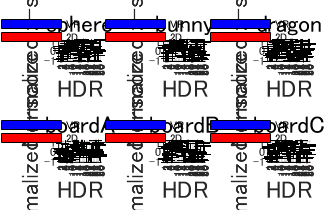



%histgram1
figure('Position',[50,50,1300,840]);
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_histgram1(Exp3HS(:,shape),err_Exp3HS(:,shape),InoueHS(:,shape),err_InoueHS(:,shape), ...
        'HDR',HDRNum_30,'Normalized z-score',string(ShapeNames(shape)),amp)
end
plotname = strcat(ana_result, '/VRvs2D_Shape_Hist.jpg');
saveas(gcf, plotname);

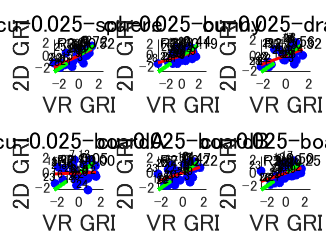

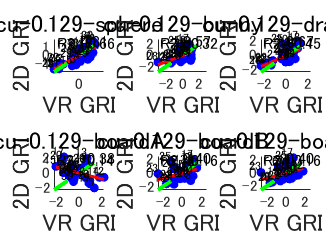

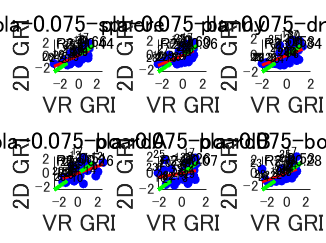

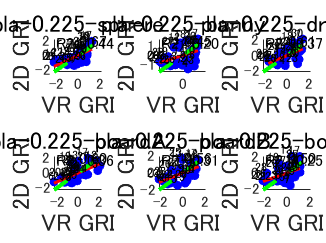

%-----------------------------------
% VR vs 2D HDR,Material,Shape coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
predim = 1;

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_plot1(Exp3HMS(:,mat,shape),InoueHMS(:,mat,shape),coef_list,slop_list, ...
            'VR GRI','2D GRI',graphtitle,HDRNum_30,amp,predim)
    end
    plotname = sprintf('%s/VRvs2D_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

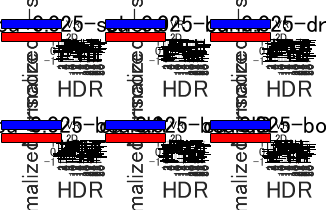

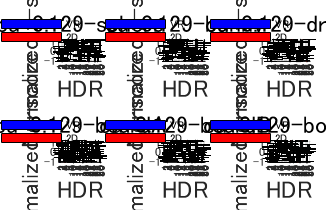

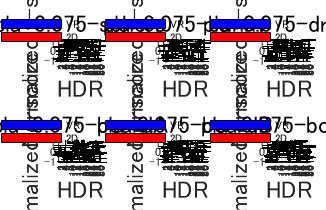

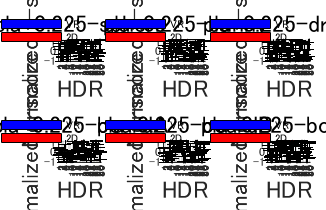


%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_histgram1(Exp3HMS(:,mat,shape),err_Exp3HMS(:,mat,shape), ...
            InoueHMS(:,mat,shape),err_InoueHMS(:,mat,shape), ...
            'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
    end
    plotname = sprintf('%s/VRvs2D_MS_%s_Hist.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

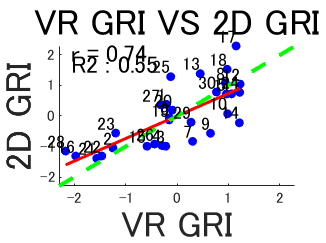

%-----------------------------------
% VR vs 2D HDR coef
%-----------------------------------
amp = 1.5;
coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D GRI');
Analysis_plot1(Exp3H(:),InoueH(:),coef_list,slop_list, ...
    'VR GRI','2D GRI',graphtitle,HDRNum_30,amp,1)
plotname = strcat(ana_result, '/VRvs2D_HDR_Coef.jpg');
saveas(gcf, plotname);

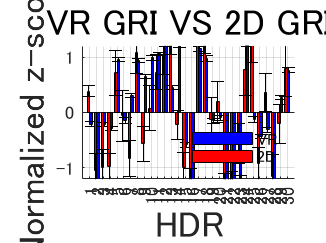


%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),InoueH(:),err_InoueH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvs2D_HDR_Hist.jpg');
saveas(gcf, plotname);

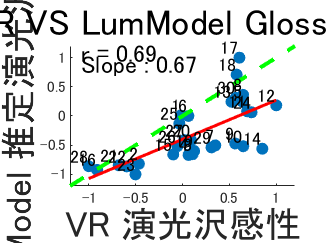

%-----------------------------------
% VR vs LumModel HDR coef
%-----------------------------------
amp = 1.5;
coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));
predim = 1;

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D GRIModel');
Analysis_plot1(Exp3H(:),LumModelH(:),coef_list,slop_list, ...
    'VR GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Coef.jpg');
saveas(gcf, plotname);

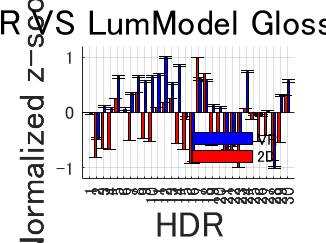


%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),LumModelH(:),Error_LumModelH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Hist.jpg');
saveas(gcf, plotname);

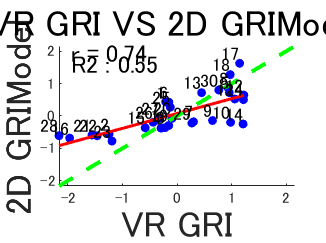

%-----------------------------------
% VR vs LumModel HDR coef
%-----------------------------------
amp = 1.5;
coef_list = [];
slop_list = [];
predim = 1;

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D GRIModel');
Analysis_plot1(Exp3H(:),LumModelH(:),coef_list,slop_list, ...
    'VR GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Coef.jpg');
saveas(gcf, plotname);

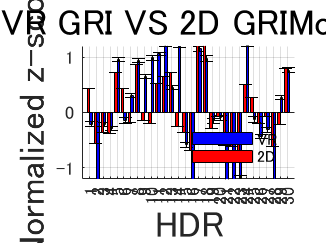


%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),LumModelH(:),Error_LumModelH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Hist.jpg');
saveas(gcf, plotname);

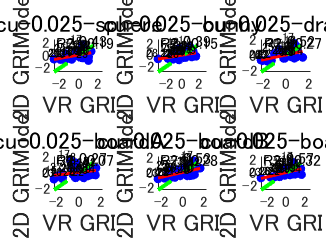

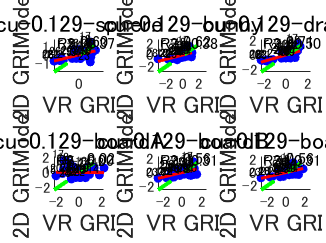

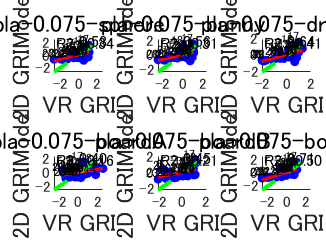

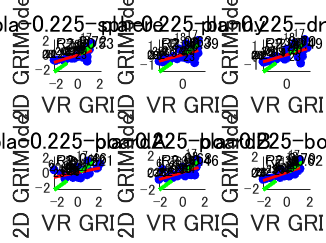

%-----------------------------------
% VR vs LumModel HDR,Material,Shape coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
predim = 1;

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_plot1(Exp3HMS(:,mat,shape),LumModelH(:),coef_list,slop_list, ...
            'VR GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
    end
    plotname = sprintf('%s/VRvsLumModel_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

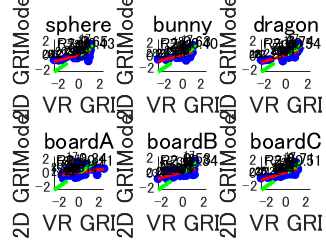

%-----------------------------------
% VR vs LumModel HDR,Shape 
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_plot1(Exp3HS(:,shape),LumModelH(:),coef_list,slop_list, ...
        'VR GRI','2D GRIModel',string(ShapeNames(shape)),HDRNum_30,amp,predim);
end
plotname = strcat(ana_result, '/VRvsLumModel_Shape_Coef.jpg');
saveas(gcf, plotname);

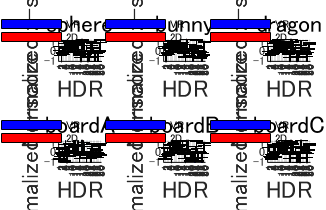



%histgram1
figure('Position',[50,50,1300,840]);
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    Analysis_histgram1(Exp3HS(:,shape),err_Exp3HS(:,shape),LumModelH(:),Error_LumModelH(:), ...
        'HDR',HDRNum_30,'Normalized z-score',string(ShapeNames(shape)),amp);
end
plotname = strcat(ana_result, '/VRvsLumModel_Shape_Hist.jpg');
saveas(gcf, plotname);

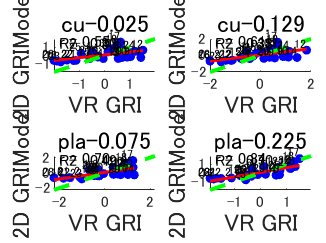

%-----------------------------------
% VR vs LumModel HDR,Material coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;

figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_plot1(Exp3HM(:,mat),LumModelH(:),coef_list,slop_list, ...
        'VR GRI','2D GRIModel',string(MatNames3(mat)),HDRNum_30,amp,predim);
end
plotname = strcat(ana_result, '/VRvsLumModel_Mat_Coef.jpg');
saveas(gcf, plotname);

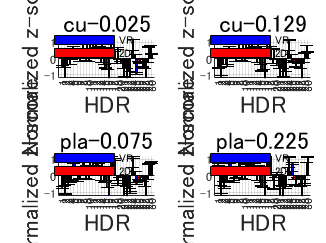


%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    Analysis_histgram1(Exp3HM(:,mat),err_Exp3HM(:,mat),LumModelH(:),Error_LumModelH(:), ...
        'HDR',HDRNum_30,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/VRvsLumModel_Mat_Hist.jpg');
saveas(gcf, plotname);

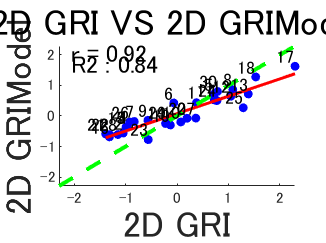

%-----------------------------------
% 2D vs LumModel HDR coef
%-----------------------------------
amp = 1.5;
coef_list = [];
slop_list = [];
predim = 1;

%散布図
figure;
graphtitle = sprintf('2D GRI VS 2D GRIModel');
Analysis_plot1(InoueH(:),LumModelH(:),coef_list,slop_list, ...
    '2D GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/2DvsLumModel_HDR_Coef.jpg');
saveas(gcf, plotname);

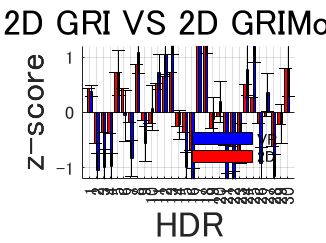


%histgram
figure;
Analysis_histgram1(InoueH(:),err_InoueH(:),LumModelH(:),Error_LumModelH(:), ...
    'HDR',HDRNum_30,'z-score',graphtitle,amp)
plotname = strcat(ana_result, '/2DvsLumModel_HDR_Hist.jpg');
saveas(gcf, plotname);

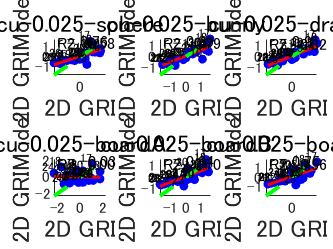

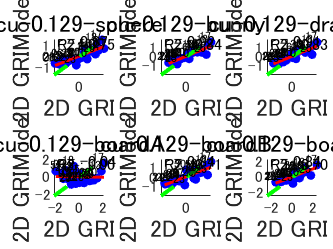

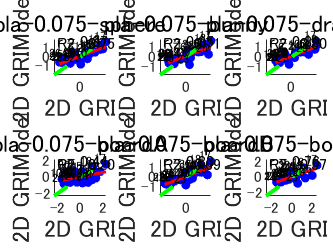

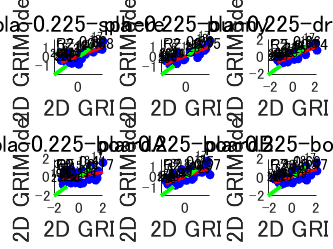

%-----------------------------------
% 2D vs LumModel HDR,Material,Shape coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
predim = 1;

for mat = 1:size(InoueHMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(InoueHMS,3)
        nexttile;

        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_plot1(InoueHMS(:,mat,shape),LumModelH(:),coef_list,slop_list, ...
            '2D GRI','2D GRIModel',graphtitle,HDRNum_30,amp,predim);
    end
    plotname = sprintf('%s/2DvsLumModel_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

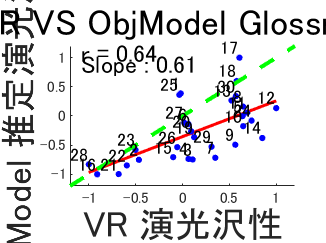

%-----------------------------------
% VR vs ObjModelNorm HDR coef
%-----------------------------------
amp = 1.5;
coef_list = [];
slop_list = [];
Error_ObjModelH = zeros(size(ObjModelH));
predim = 1;

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D ObjGRIModel');
Analysis_plot1(Exp3H(:),ObjModelH(:),coef_list,slop_list, ...
    'VR GRI','2D ObjGRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/VRvsObjNormModel_HDR_Coef.jpg');
saveas(gcf, plotname);

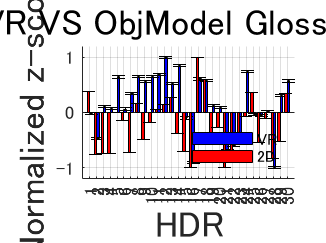


%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),ObjModelNormH(:),Error_ObjModelH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvsObjNormModel_HDR_Hist.jpg');
saveas(gcf, plotname);

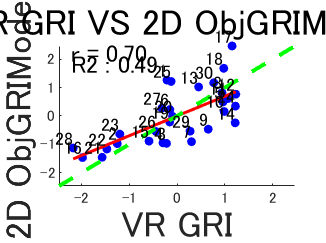

%-----------------------------------
% VR vs ObjModel HDR coef
%-----------------------------------
amp = 1.5;
coef_list = [];
slop_list = [];
Error_ObjModelH = zeros(size(ObjModelH));
predim = 1;

%散布図
figure;
graphtitle = sprintf('VR GRI VS 2D ObjGRIModel');
Analysis_plot1(Exp3H(:),ObjModelH(:),coef_list,slop_list, ...
    'VR GRI','2D ObjGRIModel',graphtitle,HDRNum_30,amp,predim);
plotname = strcat(ana_result, '/VRvsObjModel_HDR_Coef.jpg');
saveas(gcf, plotname);

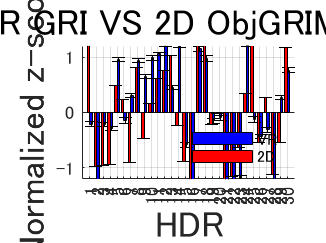


%histgram
figure;
Analysis_histgram1(Exp3H(:),err_Exp3H(:),ObjModelH(:),Error_ObjModelH(:), ...
    'HDR',HDRNum_30,'Normalized z-score',graphtitle,amp)
plotname = strcat(ana_result, '/VRvsObjModel_HDR_Hist.jpg');
saveas(gcf, plotname);

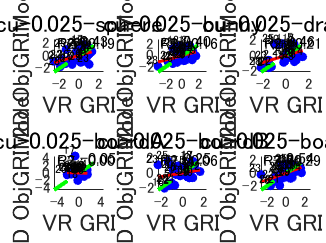

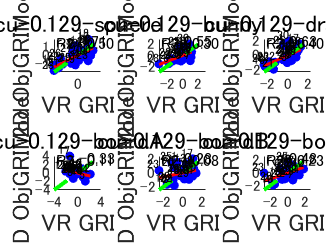

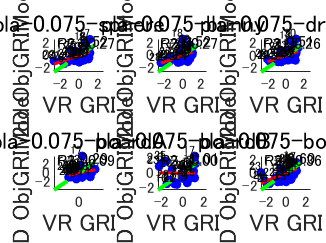

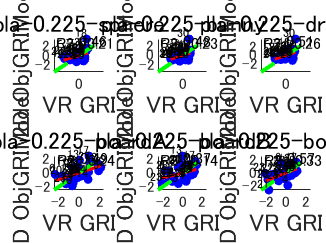

%-----------------------------------
% VR vs ObjModel HDR,Material,Shape coef
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1;
predim = 1;

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        graphtitle = sprintf('%s-%s',string(MatNames3(mat)),string(ShapeNames(shape)));
        Analysis_plot1(Exp3HMS(:,mat,shape),ObjModelHMS(:,mat,shape),coef_list,slop_list, ...
            'VR GRI','2D ObjGRIModel',graphtitle,HDRNum_30,amp,predim)
    end
    plotname = sprintf('%s/VRvsObjModel_MS_%s_Coef.jpg',ana_result,string(MatNames3(mat)));
    saveas(gcf, plotname);
end

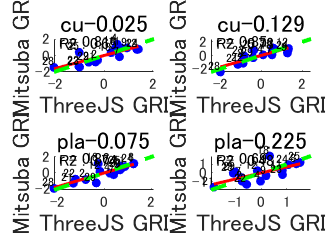

%-----------------------------------
% exp1,2 VS Hist
%-----------------------------------
%Exp1
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;
%plot
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp1ThHM15,2)
    nexttile;
    Analysis_plot1(Exp1ThHM15(:,mat),Exp1MiHM15(:,mat),coef_list,slop_list, ...
        'ThreeJS GRI','Mitsuba GRI',string(MatNames3(mat)),HDRNum_15,amp,predim);
end
plotname = strcat(ana_result, '/ThreeJSvsMitsuba_Mat_Coef.jpg');
saveas(gcf, plotname);

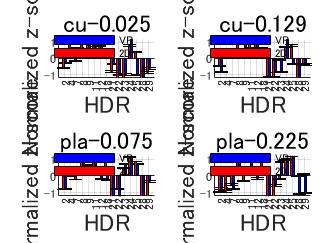

%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp1ThHM15,2)
    nexttile;
    Analysis_histgram1(Exp1ThHM15(:,mat),err_Exp1ThHM15(:,mat),Exp1MiHM15(:,mat),err_Exp1MiHM15(:,mat), ...
        'HDR',HDRNum_15,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/ThreeJSvsMitsuba_Mat_Hist.jpg');
saveas(gcf, plotname);

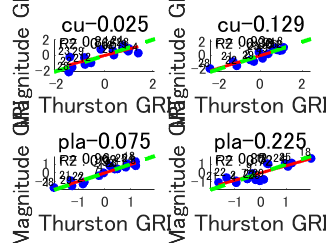



%Exp2
coef_list = [];
slop_list = [];
amp = 1.0;
predim = 1;
%plot
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp2MiHM15,2)
    nexttile;
    Analysis_plot1(Exp1MiHM15(:,mat),Exp2MiHM15(:,mat),coef_list,slop_list, ...
        'Thurston GRI','Magnitude GRI',string(MatNames3(mat)),HDRNum_15,amp,predim);
end
plotname = strcat(ana_result, '/ThurstonvsMagnitude_Mat_Coef.jpg');
saveas(gcf, plotname);

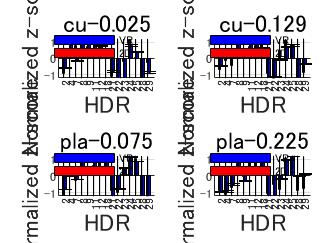

%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp2MiHM15,2)
    nexttile;
    Analysis_histgram1(Exp1MiHM15(:,mat),err_Exp1MiHM15(:,mat),Exp2MiHM15(:,mat),err_Exp2MiHM15(:,mat), ...
        'HDR',HDRNum_15,'Normalized z-score',string(MatNames3(mat)),amp)
end
plotname = strcat(ana_result, '/ThurstonvsMagnitude_Mat_Hist.jpg');
saveas(gcf, plotname);

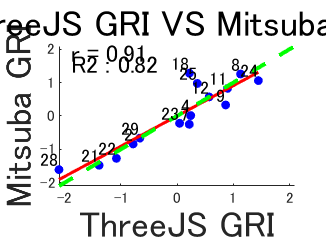

%-----------------------------------
% exp1,2 VS　Plot
%-----------------------------------
coef_list = [];
slop_list = [];
amp = 1.5;
dim = 1;

%Exp1
figure;
graphtitle = sprintf('ThreeJS GRI VS Mitsuba GRI');
Analysis_plot1(Exp1ThH15(:),Exp1MiH15(:),coef_list,slop_list, ...
    'ThreeJS GRI','Mitsuba GRI',graphtitle,HDRNum_15,amp,dim)
plotname = strcat(ana_result, '/ThreeJS vs Mitsuba_GRI.jpg');
saveas(gcf, plotname);

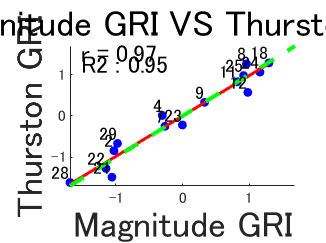


%Exp2
figure;
graphtitle = sprintf('Magnitude GRI VS Thurston GRI');
Analysis_plot1(Exp2MiH15(:),Exp1MiH15(:),coef_list,slop_list, ...
    'Magnitude GRI','Thurston GRI',graphtitle,HDRNum_15,amp,dim)
plotname = strcat(ana_result, '/Magnitude vs Thurston_GRI.jpg');
saveas(gcf, plotname);

%-----------------------------------
% exp1,exp2 VS VR HDR,material
%-----------------------------------
name1 = 'Exp1';
name2 = 'Exp2';
name3 = 'Exp3';
title = 'Exp2vsExp3_HM';
Make_2dims_vsgraph_Coef_Hist(Exp3HM15,err_Exp3HM15,Exp2ThHM15,err_Exp2ThHM15,title,name3,name2);
title = 'Exp2vsExp3_HDR';
Make_1dims_vsgraph_Coef_Hist(Exp3H15,err_Exp3H15,Exp2ThH15,err_Exp2ThH15,title,name3,name2);
title = 'Exp1vsExp3_HM';
Make_2dims_vsgraph_Coef_Hist(Exp3HM15,err_Exp3HM15,Exp1ThHM15,err_Exp1ThHM15,title,name3,name1);
title = 'Exp1vsExp3_HDR';
Make_1dims_vsgraph_Coef_Hist(Exp3H15,err_Exp3H15,Exp1ThH15,err_Exp1ThH15,title,name3,name1);

%-----------------------------------
% exp1,exp2 VS Old HDR,material
%-----------------------------------
name1 = 'Exp1';
name2 = 'Exp2';
name3 = 'Old';
errorinoue1 = zeros(size(InoueHM15));
errorinoue2 = zeros(size(InoueH15));

title = 'Exp2vsOld_HM';
Make_2dims_vsgraph_Coef_Hist(InoueHM15,errorinoue1,Exp2MiHM15,err_Exp2MiHM15,title,name3,name2);
title = 'Exp2vsOld_HDR';
Make_1dims_vsgraph_Coef_Hist(InoueH15,errorinoue2,Exp2MiH15,err_Exp2MiH15,title,name3,name2);
title = 'Exp1vsOld_HM';
Make_2dims_vsgraph_Coef_Hist(InoueHM15,errorinoue1,Exp1MiHM15,err_Exp1MiHM15,title,name3,name1);
title = 'Exp1vsOld_HDR';
Make_1dims_vsgraph_Coef_Hist(InoueH15,errorinoue2,Exp1MiH15,err_Exp1MiH15,title,name3,name1);

%{
%-----------------------------------
% Exp3 Material Shape
%-----------------------------------
for mat = 1:size(Exp3HMS,2)
    figure;
    hold on;
    for shape = 1:size(Exp3HMS,3)
        subplot(2, 3, shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, Exp3HMS(:,mat, shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        errorbar(x + bar_width/2, Exp3HMS(:,mat,shape), err_Exp3HMS(:,mat,shape), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' MatNames2{mat} '&' ShapeNames{shape}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Exp3_MS_', MatNames2{mat},'.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Exp3 Material
%-----------------------------------
figure;
hold on;
for mat = 1:4
    subplot(2, 2, mat);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HM(:,mat), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HM(:,mat), error_Exp3HMSNorm(:,mat), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
end
plotname = strcat(ana_result, '/Exp3_Material', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 Shape
%-----------------------------------
figure;
hold on;
for shape = 1:size(Exp3HS,2)
    subplot(2,3,shape);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HS(shape, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HS(shape, :), error_Exp3HSNorm(shape,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' ShapeNames{shape}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');

end
plotname = strcat(ana_result, '/Exp3_', 'Shape','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 HDR
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb = bar(x + bar_width/2, Exp3H, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, Exp3H, error_Exp3HNorm, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Normalized z-score', 'FontSize', 16);
title('HDR', 'FontSize', 16);
plotname = strcat(ana_result, '/Exp3_HDR.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material
%-----------------------------------
figure;
hold on;
for mat = 1:size(InoueHM,2)
    subplot(2,2,mat);
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueMHNorm(:,mat), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueMHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueMatname{mat}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Material','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue Shape
%-----------------------------------
figure;
hold on;
for shape = 1:size(InoueHS,2)
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueSHNorm(:,shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueSHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Normalized z-score', 'FontSize', 16);
    title(['compare of ' InoueShapeName{shape}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Shape', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material shape
%-----------------------------------
for mat = 1:size(InoueHMS,2)
    figure;
    hold on;
    for shape = 1:size(InoueHMS,3)
        subplot(2,3,shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, InoueHMS(:,mat, shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        %errorbar(x + bar_width/2, InoueMHSNorm(:,matnum, shapenum), error_Exp3MHS(matnum,:,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' InoueMatname{mat} '&' InoueShapeName{row}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Old_MS_', InoueMatname{mat},'.jpg');
    saveas(gcf, plotname);
    hold off;
end
%}

%{
%-----------------------------------
% Exp3 vs Old HDR coef
%-----------------------------------
Exp3HMS_reshaped = reshape(Exp3HMS,size(Exp3HMS,1),[]);
InoueHMS_reshaped = reshape(InoueHMS,size(InoueHMS,1),[]);

coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));
amp = 1.0;

% coef and slope
for hdr = 1:size(Exp3H)
    x = Exp3HMS(hdr,:,:);
    y = InoueHMS(hdr,:,:);
    r = corrcoef(x,y);
    r_value = r(1,2);
    coef_list(hdr) = r_value;
    p = polyfit(x,y,1);
    slop_list(hdr) = p(1);
end

% coef hisgram
figure;
hold on;
x = 1:length(coef_list);
bar_width = 0.4;
bar_coef = bar(x,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_coef = bar(x - bar_width/2,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_slope = bar(x + bar_width/2,slop_list,bar_width, 'FaceColor', 'r', 'DisplayName', 'Slope');
for i = 1:length(coef_list)
    graphtext1 = sprintf('%.2f',coef_list(i));
    text(i,(abs(coef_list(i))+0.06)*coef_list(i)/abs(coef_list(i)),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',8*amp);
    %graphtext2 = sprintf('%.2f',slop_list(i));
    %text(i + bar_width/2,slop_list(i),graphtext2,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
end
ylim([-0.55 1.0]);
set(gca, 'XTick', x);
xticklabels(HDRNames3);
set(gca,'FontSize',8*amp);
xlabel('HDR','FontSize',18*amp);
ylabel('Coef','FontSize',18*amp);
title(sprintf('VR VS 2D Coef about HDR'),'FontSize',18*amp);
%legend([bar_coef, bar_slope], {'Coef', 'Slope'}, 'Location', 'best','Orientation','vertical');
legend(bar_coef, 'Coef', 'Location', 'northeast','Orientation','vertical');
text(0,0.95, '* : p-value < 0.05', 'FontSize', 15*amp);
grid on;
hold off;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coefbar.jpg');
saveas(gcf, plotname);
%}

%{
%-----------------------------------
% Exp3 vs Old all coef
%-----------------------------------
amp = 1.5;

%散布図
figure;
x = Exp3H(:);
y = InoueH(:);
r = corrcoef(x,y);
r_value = r(1,2);
p = polyfit(x,y,1);
p_fit = polyval(p,x);

scatter(x,y,'filled');
hold on;
%plot(x,p_fit,'r-','LineWidth',1.5);

xlim([-1.5 1.0]);
x_limits = xlim;
%ylim([-1.2 1.2]);
y_limits = ylim;
common_limits = [min([x_limits, y_limits]), max([x_limits, y_limits])];
plot(common_limits, common_limits, 'r--', 'LineWidth', 2);
% グラフ囲む
rectangle('Position', [x_limits(1), y_limits(1), diff(x_limits), diff(y_limits)], ...
          'EdgeColor', 'k', 'LineWidth', 0.75);
% HDR No
for point = 1:length(x)
    text(x(point)-0.01, y(point)+0.01, num2str(HDRNames3(point)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right','FontSize',8*amp);
end
hold off;

text(x_limits(1)*0.95,y_limits(2)*0.95, 'Luminance image No.', 'FontSize', 8*amp);
set(gca,'FontSize',8*amp);
xlabel('VR Z-score','FontSize',12*amp);
ylabel('2D Z-score','FontSize',12*amp);
%title(sprintf('VR VS 2D Glossness\n correlation coefficient : %.2f,Slope : %.2f', r_value,p(1)));
title(sprintf('VR VS 2D Glossness\n correlation coefficient : %.2f', r_value),'FontSize',10*amp);
grid on;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coef.jpg');
saveas(gcf, plotname);


%histgram2
bar1 = Exp3H(:);
err1 = err_Exp3H(:);
bar2 = InoueH(:);

figure;
bar_width = 0.35;
x = 1:length(HDRNames);

hold on;
bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
%errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
hold off;

ylim([-1.2 1.2]);
set(gca, 'XTick', x);
xticklabels(HDRNames3);
xtickangle(90);
set(gca,'FontSize',6*amp);

xlabel('HDR','FontSize',12*amp); 
ylabel('Normalized z-score','FontSize',12*amp);
title(sprintf('HDR: Coef = %.2f,Slope = %.2f', r_value,p(1)),'FontSize',12*amp);
legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
legend('boxoff');
grid on;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Hist.jpg');
saveas(gcf, plotname);
%}

%{
% coef hisgram
figure;
hold on;
x = 1:length(coef_list);
bar_width = 0.4;
bar_coef = bar(x,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_coef = bar(x - bar_width/2,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_slope = bar(x + bar_width/2,slop_list,bar_width, 'FaceColor', 'r', 'DisplayName', 'Slope');
for i = 1:length(coef_list)
    graphtext1 = sprintf('%.2f',coef_list(i));
    text(i - bar_width/2,coef_list(i),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    %graphtext2 = sprintf('%.2f',slop_list(i));
    %text(i + bar_width/2,slop_list(i),graphtext2,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    if S_p_value(i) < 0.05
        graphtext3 = sprintf('*');
        text(i,max(coef_list(i),slop_list(i))+0.05,graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    end
end
ylim([0 1.0]);
set(gca, 'XTick', x);
xticklabels(ShapeNames);
set(gca,'FontSize',12*amp);
xlabel('Shape types','FontSize',18*amp);
ylabel('Value','FontSize',18*amp);
title(sprintf('VR VS 2D Coef about Shape'),'FontSize',18*amp);
%legend([bar_coef, bar_slope], {'Coef', 'Slope'}, 'Location', 'best','Orientation','vertical');
legend(bar_coef, 'Coef', 'Location', 'best','Orientation','vertical');
text(0,0.95, '* : p-value < 0.05', 'FontSize', 15*amp);
hold off;
plotname = strcat(ana_result, '/Exp3vsOld_Shape_Coefbar.jpg');
saveas(gcf, plotname);
%}